 % Experiment-2: Whole Image as Input: Apply Transfer Learning with ResNet-50
% Author: Sujan Khanal
% ID: u3258630

close all;
clear variables;
clc;

rng(42, 'twister'); %% For reproducibility

%% STEP 1: Check and Reset GPU
if (gpuDeviceCount() > 0)
    disp('Found GPU:');
    disp(gpuDeviceTable);
    device = gpuDevice(1);
    reset(device); % Reset any old data
else
    error('No GPU device found. Please ensure GPU is available.');
end

Found GPU:


    Index              Name               ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce RTX 3070"          "8.6"               true              true      



## Read the training, validation and test partitions from the relevant

%% Load Dataset Information
folder = "C:\Users\u3258630\Desktop\CVIA\u3258630_CVIA_Asgn1_Final\CUB_200_2011\";

trainingImageNames = readtable(fullfile(folder, "train200.txt"), ...
    'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(folder + "validate200.txt", ...
    'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(folder + "test200.txt", ...
    'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

## Read class info from the relevant text files

classNames = readtable(folder + "classes.txt", ...
    'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(folder + "image_class_labels.txt", ...
    'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

## Create lists of image names for training, validation and test subsets.

%% Build Image Lists
trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

## Create image datastores for training, validation and test subsets

%% Create ImageDatastores
trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Training set class distribution:');

Training set class distribution:


countEachLabel(trainingImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  



validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Validation set class distribution:');

Validation set class distribution:


countEachLabel(validationImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  



testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Test set class distribution:');

Test set class distribution:


countEachLabel(testImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  


## The images all have different spatial resolutions (width x height), so

targetSize = [224, 224];

trainingImageDS_Resized = transform(trainingImageDS, @(x) imresize(x,targetSize));
validationImageDS_Resized = transform(validationImageDS, @(x) imresize(x,targetSize));
testImageDS_Resized = transform(testImageDS, @(x) imresize(x,targetSize));

% Combine transformed datastores and labels
labelsTraining = arrayDatastore(trainingImageDS.Labels);
cdsTraining = combine(trainingImageDS_Resized, labelsTraining);

labelsValidation = arrayDatastore(validationImageDS.Labels);
cdsValidation = combine(validationImageDS_Resized, labelsValidation);

labelsTest = arrayDatastore(testImageDS.Labels);
cdsTest = combine(testImageDS_Resized, labelsTest);

## Display a sample image from the datastore

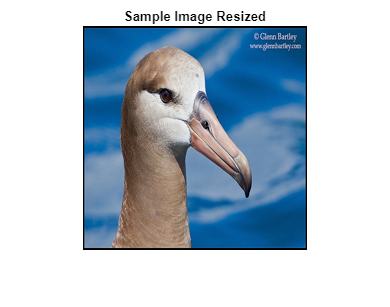

figure(1);
imshow(cdsTraining.read{1});
title('Sample Image Resized');


reset(cdsTraining); % Reset after reading once

## Load Pretrained ResNet-50 and Modify for 20 Classes

net = resnet50;
lgraph = layerGraph(net);
numClasses = 200; % For CUB-200 class

% Create new layers
newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);

newClassLayer = classificationLayer('Name','new_classoutput');

% Find names of layers to replace
lgraph = replaceLayer(lgraph, 'fc1000', newLearnableLayer);
lgraph = replaceLayer(lgraph, 'ClassificationLayer_fc1000', newClassLayer);

## Setting Training Options

%% STEP 8: Set Training Options
options = trainingOptions('sgdm', ...
    'MiniBatchSize', 16, ...
    'MaxEpochs', 20, ...
    'InitialLearnRate', 1e-4, ...
    'ValidationData', cdsValidation, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', true, ...
    'ValidationFrequency', floor(numel(trainingImageDS.Files)/16), ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'gpu', ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 7);

## Train ResNet-50

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:47 |        0.00% |        0.30% |       5.7762 |       5.7350 |      1.0000e-04 |
|       1 |          50 |       00:00:58 |        0.00% |              |       5.9399 |              |      1.0000e-04 |
|       1 |         100 |       00:01:13 |        6.25% |              |       5.4434 |              |      1.0000e-04 |
|       1 |         150 |       00:01:29 |        6.25% |              |       4.9019 |              |      1.0000

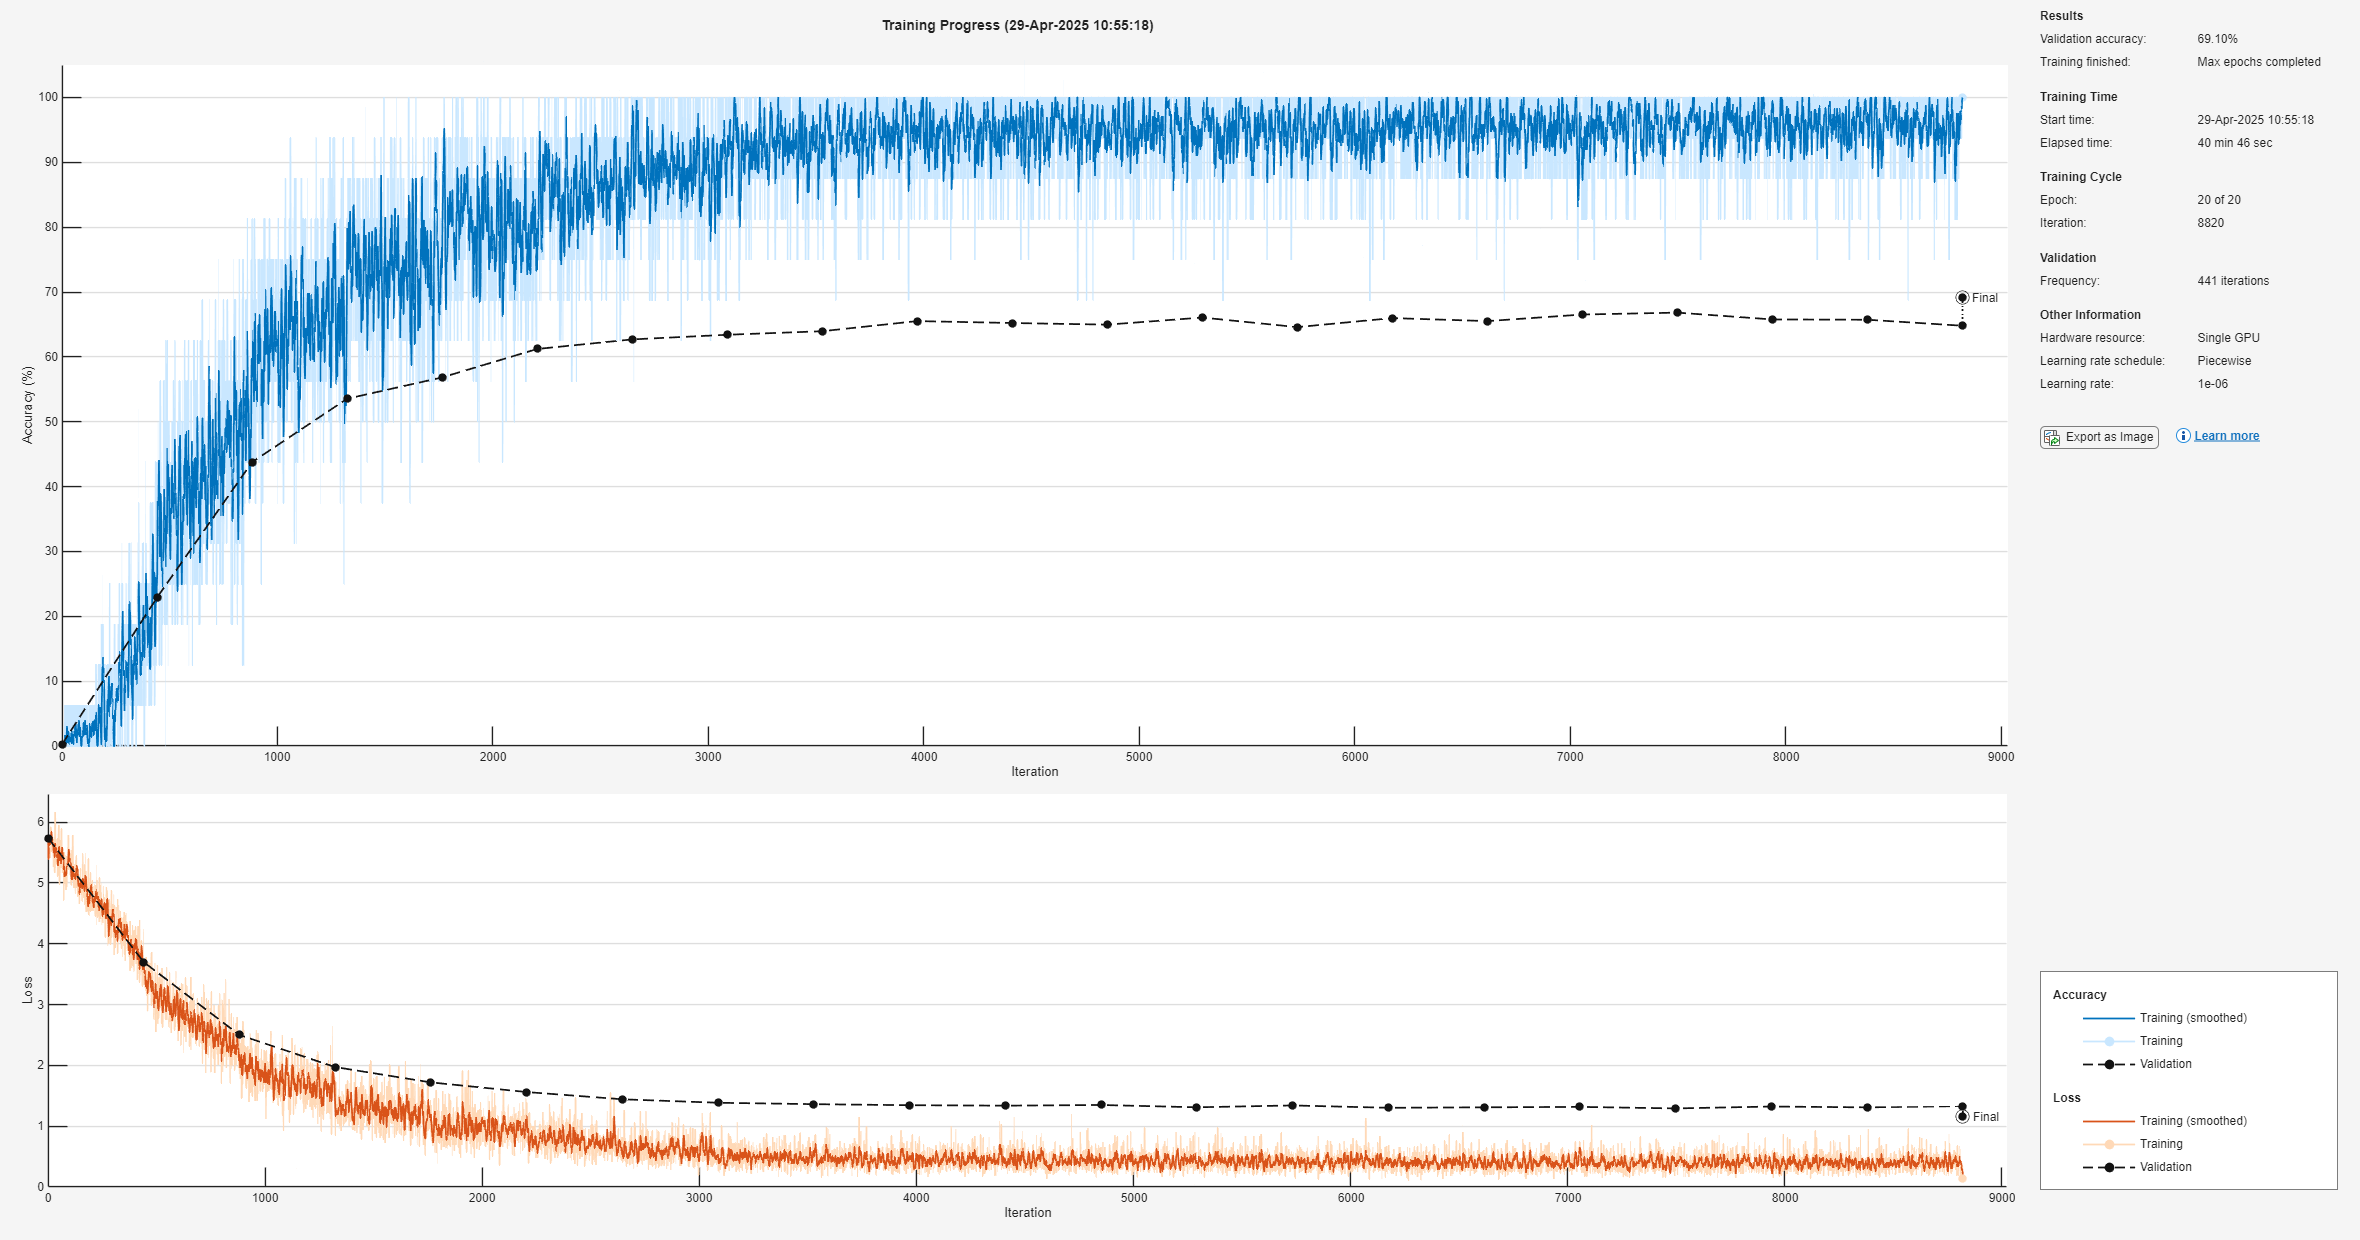

resnet50_trained = trainNetwork(cdsTraining, lgraph, options);

## Test the accuracy on the test partition

%% Evaluate Model on Test Data
YPred = classify(resnet50_trained, testImageDS_Resized, 'ExecutionEnvironment', 'gpu');
YTest = testImageDS.Labels;

% Training Prediction
YPredTrain = classify(resnet50_trained, trainingImageDS_Resized, 'ExecutionEnvironment', 'gpu');
YTrain = trainingImageDS.Labels;

% Validation Prediction
YPredValidation = classify(resnet50_trained, validationImageDS_Resized, 'ExecutionEnvironment', 'gpu');
YValidation = validationImageDS.Labels;

% Accuracy Calculations
trainAccuracy = sum(YPredTrain == YTrain) / numel(YTrain);
validationAccuracy = sum(YPredValidation == YValidation) / numel(YValidation);
testAccuracy = sum(YPred == YTest) / numel(YTest);

% Display Accuracies
disp(['Training Accuracy (ResNet-50): ', num2str(trainAccuracy*100, '%.2f'), '%']);

Training Accuracy (ResNet-50): 97.92%


disp(['Validation Accuracy (ResNet-50): ', num2str(validationAccuracy*100, '%.2f'), '%']);

Validation Accuracy (ResNet-50): 69.10%


disp(['Test Accuracy (ResNet-50): ', num2str(testAccuracy*100, '%.2f'), '%']);

Test Accuracy (ResNet-50): 66.61%


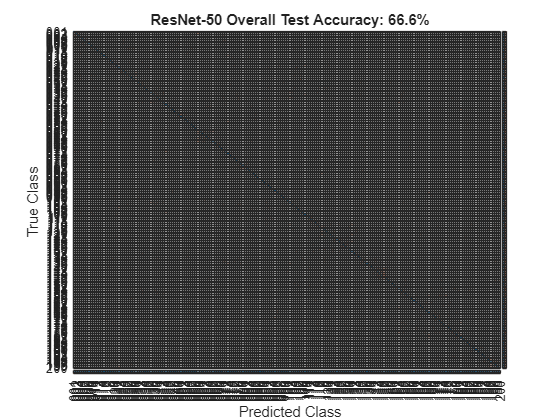


%% STEP 11: Confusion Matrix
[m, order] = confusionmat(YTest, YPred);

figure(2);
cm = confusionchart(m, order, ...
    'ColumnSummary', 'column-normalized', ...
    'RowSummary', 'row-normalized');
title("ResNet-50 Overall Test Accuracy: " + string(round(testAccuracy*100,1)) + "%");